format long

p1 = [0 -1 1];
p2 = [0 1 -2];

p2p1 = p2-p1

p2p1 =      0     2    -3


norm_p2p1 = norm(p2p1)

norm_p2p1 =    3.605551275463989



p2p1_versor = p2p1 / norm_p2p1

p2p1_versor =                    0   0.554700196225229  -0.832050294337844



x = [p1(2) p2(2)];                                              % Create Data
y = [p1(3) p2(3)];                                              % Create Data
N = 1000000;                                                  % Number Of Segments
xi = linspace(x(1), x(2), N+1);                         % Interpolation Vector
yi = interp1(x, y, xi, 'linear');                       % Find ‘yi’ For Each ‘xi’

figure(1)
plot(x, y, '-o')
hold on
axis equal
plot(xi(2:end-1), yi(2:end-1), '-')

grid

new_point = [1; 2/3];
plot(new_point(1), new_point(2), 's')


points = [xi; yi];
norms = vecnorm(points-new_point).^2; % SQUARED!

[min_norm, smaller_norm_idx] = min(norms)

min_norm =    2.188034188036111


smaller_norm_idx =       384616



closest = points(:,smaller_norm_idx)

closest =   -0.230770000000000
  -0.153845000000000


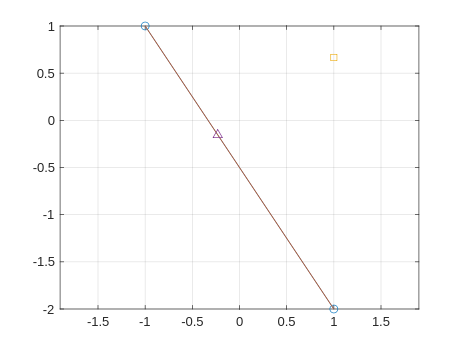


plot(closest(1), closest(2), '^')


squared_norm_of_closest = norm(closest)^2

squared_norm_of_closest =    0.076923076925000



squared_norm_of_distance = norm(new_point-closest)^2

squared_norm_of_distance =    2.188034188036111


## Check orientation

Z-Y Euler Angles (N.B.: code is NOT general)

theta_z = deg2rad(90)

theta_z =    1.570796326794897


theta_y = -atan2(p2p1(3), p2p1(2))

theta_y =    0.982793723247329
